## Frequency domain inter and intra user variance data 

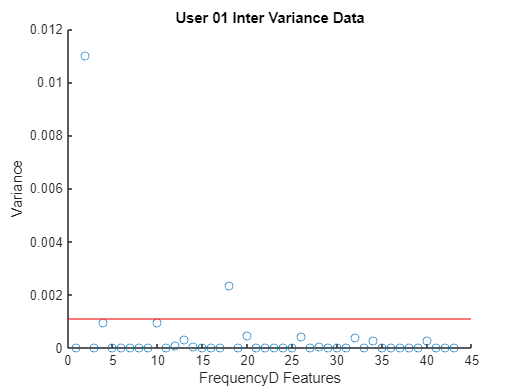

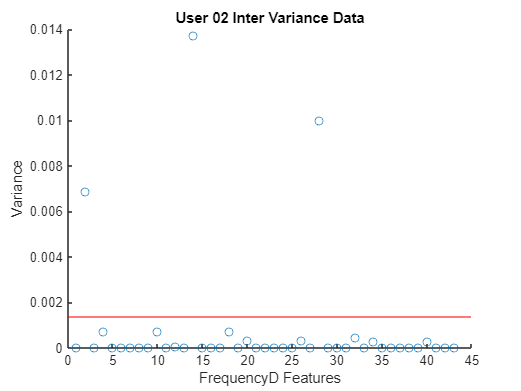

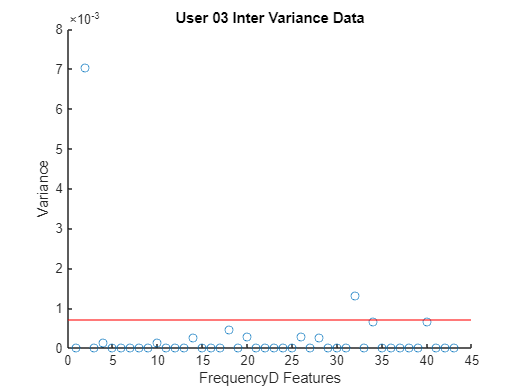

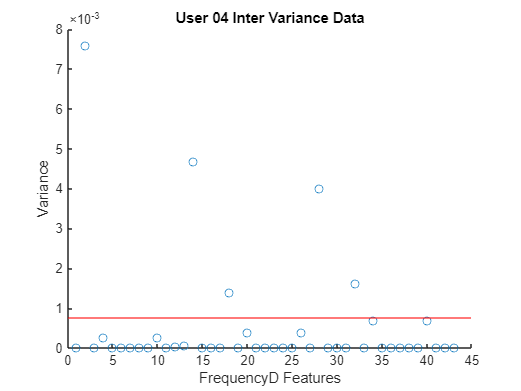

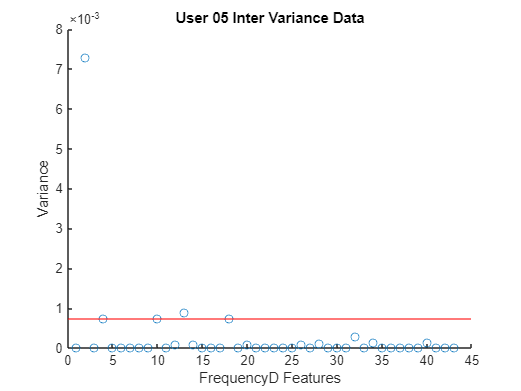

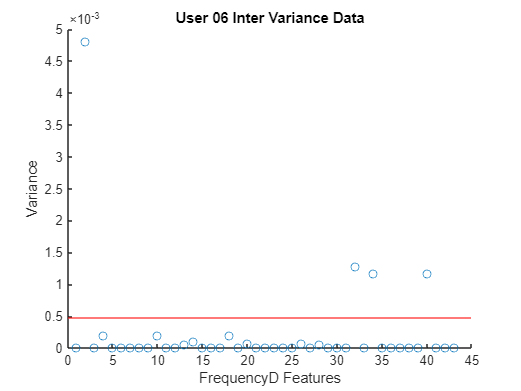

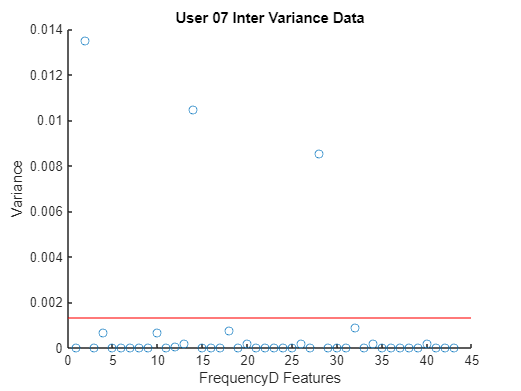

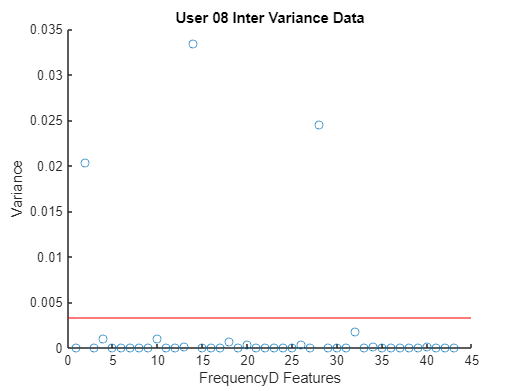

% Loop through 10 users to analyze FirstDay data 
for nu=1:10 
% Load Frequency Domain data for the FirstDay for the current user 
FreqD_FDay=load(sprintf("U%02d_Acc_FreqD_FDay.mat",nu)); 
 
% Extract the feature vector (dimensions: 36 x 43) 
FreqD_FDay_Feat_Vec=FreqD_FDay.Acc_FD_Feat_Vec(1:36,1:43); 
 
% Compute statistical properties of the feature vector 
M=mean(FreqD_FDay_Feat_Vec);% Mean of each feature 
V=var(FreqD_FDay_Feat_Vec);% Variance of each feature 
Stan_D=std(FreqD_FDay_Feat_Vec);% Standard deviation of each feature 
 
% Find the maximum variance value 
Maximum_V=max(V); 
 
% Plot variance as a scatter plot 
figure 
FreqD_Inter_Var=scatter(1:43,V);% Plot variance for 43 features 
yline(Maximum_V/10,'red'); % Add a horizontal line at 10% of max variance 
 
% Add title and labels 
title(sprintf('User %02d Inter Variance Data',nu)); 
xlabel('FrequencyD Features'); 
ylabel('Variance'); 
end 

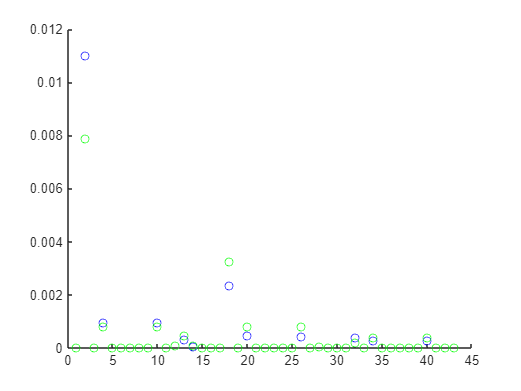

Unrecognized function or variable 'Page'.

 
% Loop through 10 users to analyze and compare FirstDay and SecondDay data 
for nu=1:10 
% Load Frequency Domain data for the FirstDay and SecondDay 
FreqD_FDay=load(sprintf("U%02d_Acc_FreqD_FDay.mat",nu)); 
FreqD_MDay=load(sprintf("U%02d_Acc_FreqD_MDay.mat",nu)); 
 
% Extract feature vectors (dimensions: 36 x 43) 
FreqD_FDay_Feat_Vec=FreqD_FDay.Acc_FD_Feat_Vec(1:36,1:43); 
FreqD_MDay_Feat_Vec=FreqD_MDay.Acc_FD_Feat_Vec(1:36,1:43); 
 
% Compute statistical properties for both days 
M=mean(FreqD_FDay_Feat_Vec);% Mean of FirstDay features 
M1=mean(FreqD_MDay_Feat_Vec);% Mean of SecondDay features 
V=var(FreqD_FDay_Feat_Vec);% Variance of FirstDay features 
V1=var(FreqD_MDay_Feat_Vec);% Variance of SecondDay features 
Stan_D=std(FreqD_FDay_Feat_Vec);% Std. dev. of FirstDay features 
Stan_D1=std(FreqD_MDay_Feat_Vec);% Std. dev. of SecondDay features 
 
% Plot variance for both days as scatter plots 
figure 
FreqD_Intra_Var=scatter(1:43,V,'blue');% FirstDay variance in blue 
hold on; 
FreqD_Intra_Var1=scatter(1:43,V1,'green');% SecondDay variance in green  
 
hold off; 
 
% Add title, labels, and legend 
title(sprintf('User %02d Intra Variance Data',nu)); 
xlabel('FrequencyD Features'); 
ylabel('Variance'); 
legend('FirstDay','SecondDay'); 
end 

## Time domain inter and intra user variance data 

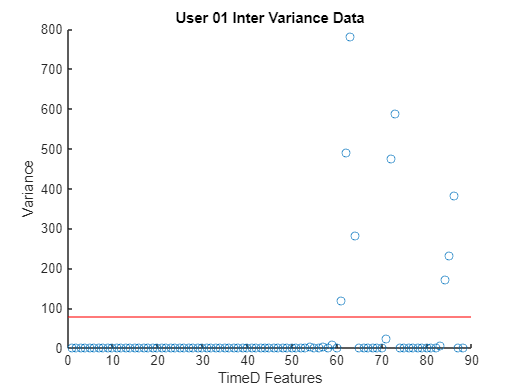

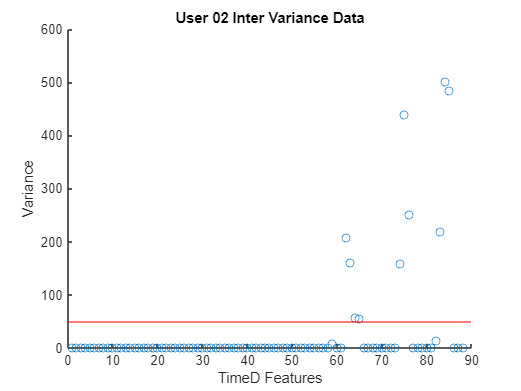

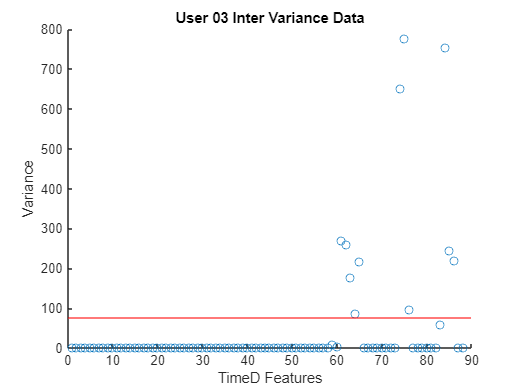

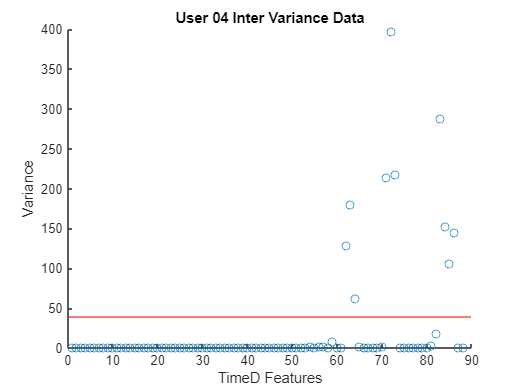

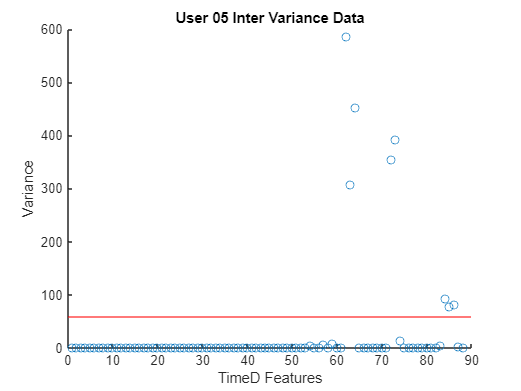

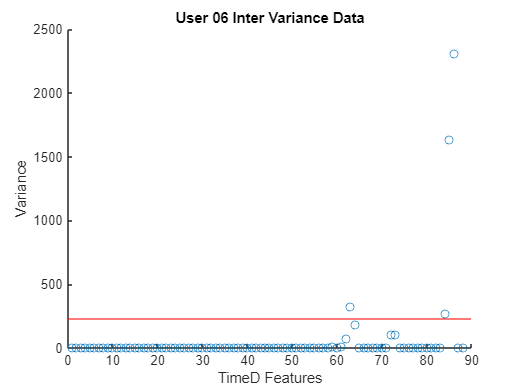

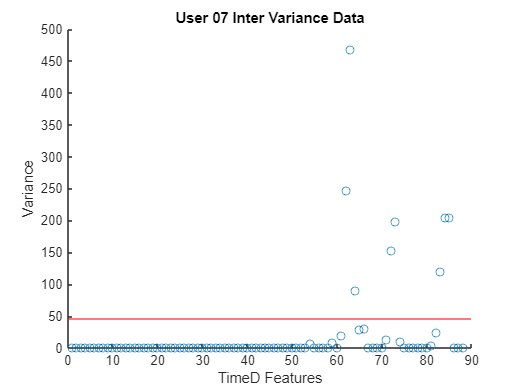

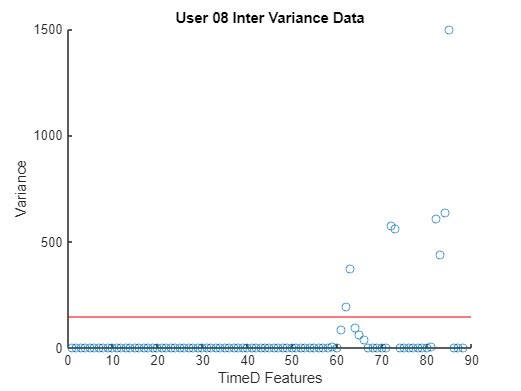

% Loop through 10 users to analyze FirstDay data 
for nu=1:10 
% Load Time Domain data for the FirstDay for the current user 
TimeD_FDay=load(sprintf("U%02d_Acc_TimeD_FDay.mat",nu)); 
 
% Extract the feature vector (dimensions: 36 x 88) 
TimeD_FDay_Feat_Vec=TimeD_FDay.Acc_TD_Feat_Vec(1:36,1:88); 
 
% Compute statistical properties of the feature vector 
M=mean(TimeD_FDay_Feat_Vec);% Mean of each feature 
V=var(TimeD_FDay_Feat_Vec);% Variance of each feature 
Stan_D=std(TimeD_FDay_Feat_Vec);% Standard deviation of each feature 
 
% Find the maximum variance value 
Maximum_V=max(V); 
 
% Plot variance as a scatter plot 
figure 
TimeD_Inter_Var=scatter(1:88,V);% Plot variance for 88 features 
yline(Maximum_V/10,'red');% Add a horizontal line at 10% of max variance 
% Add title and labels 
title(sprintf('User %02d Inter Variance Data',nu)); 
xlabel('TimeD Features'); 
ylabel('Variance'); 
end 

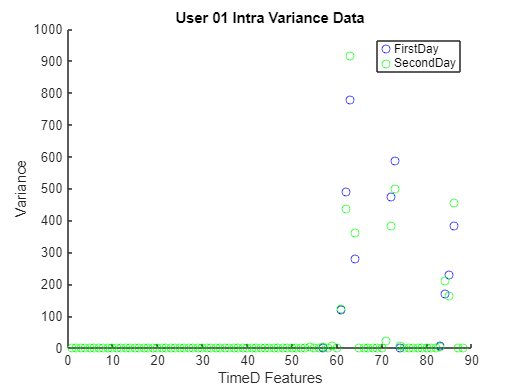

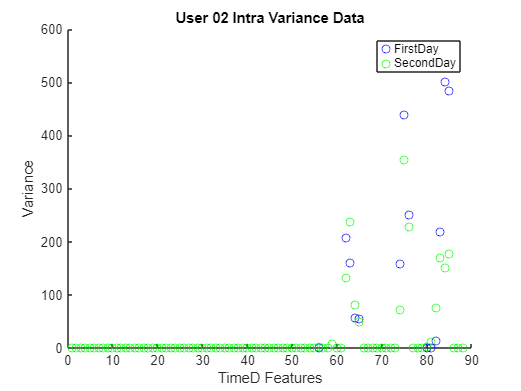

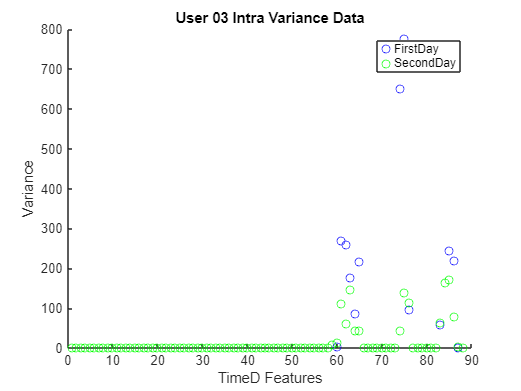

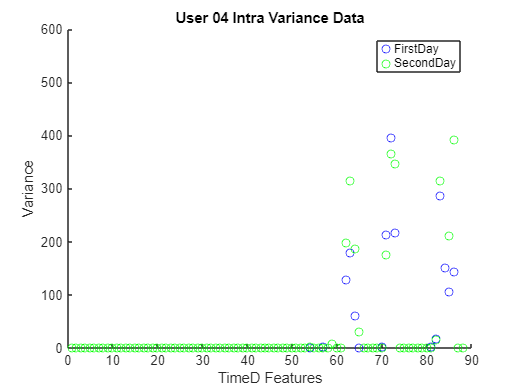

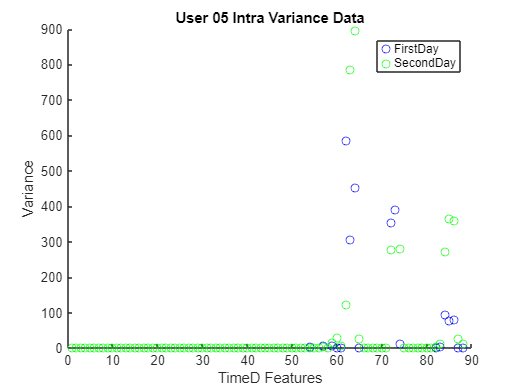

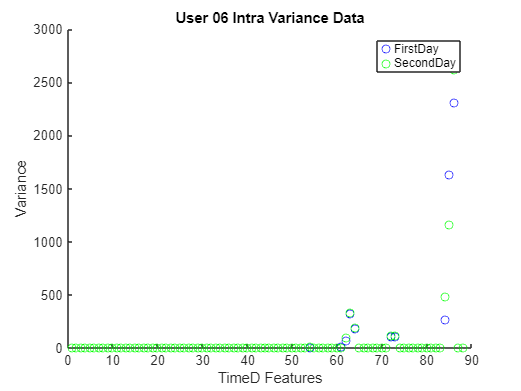

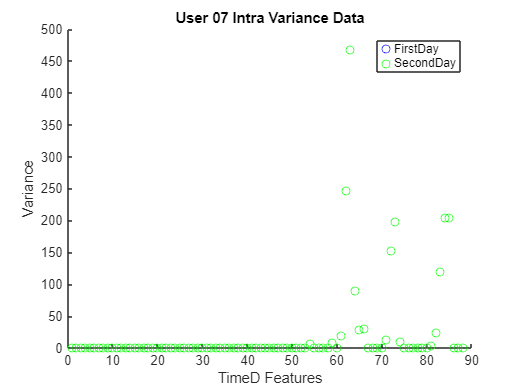

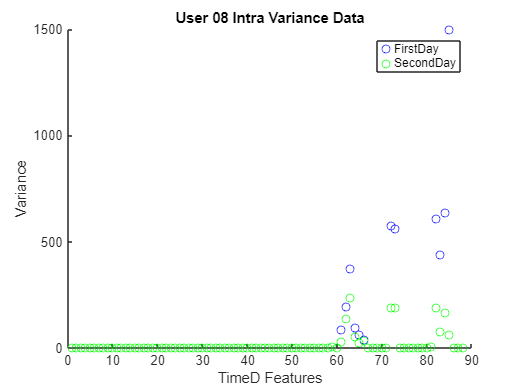

 
% Loop through 10 users to analyze and compare FirstDay and SecondDay data 
for nu=1:10 
% Load Time Domain data for the FirstDay and SecondDay 
TimeD_FDay=load(sprintf("U%02d_Acc_TimeD_FDay.mat",nu)); 
TimeD_MDay=load(sprintf("U%02d_Acc_TimeD_MDay.mat",nu)); 
 
% Extract feature vectors (dimensions: 36 x 88) 
TimeD_FDay_Feat_Vec=TimeD_FDay.Acc_TD_Feat_Vec(1:36,1:88); 
TimeD_MDay_Feat_Vec=TimeD_MDay.Acc_TD_Feat_Vec(1:36,1:88); 
 
% Compute statistical properties for both days 
M=mean(TimeD_FDay_Feat_Vec);% Mean of FirstDay features 
M1=mean(TimeD_MDay_Feat_Vec);% Mean of SecondDay features 
V=var(TimeD_FDay_Feat_Vec);% Variance of FirstDay features 
V1=var(TimeD_MDay_Feat_Vec);% Variance of SecondDay features 
Stan_D=std(TimeD_FDay_Feat_Vec);% Std. dev. of FirstDay features 
Stan_D1=std(TimeD_MDay_Feat_Vec);% Std. dev. of SecondDay features 
 
% Plot variance for both days as scatter plots 
figure 
TimeD_Intra_Var=scatter(1:88,V,'blue');% FirstDay variance in blue 
hold on; 
TimeD_Intra_Var1=scatter(1:88,V1,'green');% SecondDay variance in green 
hold off; 
 
% Add title, labels, and legend 
title(sprintf('User %02d Intra Variance Data',nu)); 
xlabel('TimeD Features'); 
ylabel('Variance'); 
legend('FirstDay','SecondDay'); 
end 

## Frequency and Time combined domain inter and intra user variance data

% Loop through 10 users to analyze FirstDay data 
for nu=1:10 
% Load Time and Frequency Domain data for the FirstDay for the current user 
TimeD_FreqD_FDay=load(sprintf("U%02d_Acc_TimeD_FreqD_FDay.mat",nu)); 
 
% Extract the feature vector (dimensions: 36 x 43) 
TimeD_FreqD_FDay_Feat_Vec=TimeD_FreqD_FDay.Acc_TDFD_Feat_Vec(1:36,1:131); 
 
% Compute statistical properties of the feature vector 
M=mean(TimeD_FreqD_FDay_Feat_Vec);% Mean of each feature 
V=var(TimeD_FreqD_FDay_Feat_Vec);% Variance of each feature 
Stan_D=std(TimeD_FreqD_FDay_Feat_Vec);% Standard deviation of each feature 
 
% Plot variance as a scatter plot 
figure 
TimeD_FreqD_Inter_Var=scatter(1:131,V);% Plot variance for 131 features 
 
% Add title and labels 
title(sprintf('User %02d Inter Variance Data',nu)); 
xlabel('TimeD and FrequencyD Features'); 
ylabel('Variance'); 
end 
 
% Loop through 10 users to analyze and compare FirstDay and SecondDay data 
for nu=1:10 
% Load Time and Frequency Domain data for the FirstDay and SecondDay 
TimeD_FreqD_FDay=load(sprintf("U%02d_Acc_TimeD_FreqD_FDay.mat",nu)); 
TimeD_FreqD_MDay=load(sprintf("U%02d_Acc_TimeD_FreqD_MDay.mat",nu)); 
 
% Extract feature vectors (dimensions: 36 x 131) 
TimeD_FreqD_FDay_Feat_Vec=TimeD_FreqD_FDay.Acc_TDFD_Feat_Vec(1:36,1:131); 
TimeD_FreqD_MDay_Feat_Vec=TimeD_FreqD_MDay.Acc_TDFD_Feat_Vec(1:36,1:131); 
 
% Compute statistical properties for both days 
M=mean(TimeD_FreqD_FDay_Feat_Vec);% Mean of FirstDay features 
M1=mean(TimeD_FreqD_MDay_Feat_Vec);% Mean of SecondDay features 
V=var(TimeD_FreqD_FDay_Feat_Vec);% Variance of FirstDay features 
V1=var(TimeD_FreqD_MDay_Feat_Vec);% Variance of SecondDay features 
Stan_D=std(TimeD_FreqD_FDay_Feat_Vec);% Std. dev. of FirstDay features 
Stan_D1=std(TimeD_FreqD_MDay_Feat_Vec);% Std. dev. of SecondDay features 
 
% Plot variance for both days as scatter plots 
figure 
TimeD_FreqD_Intra_Var=scatter(1:131,V,'blue');% FirstDay variance in blue 
hold on; 
TimeD_FreqD_Intra_Var1=scatter(1:131,V1,'green');% SecondDay variance in green 
hold off; 
 
% Add title, labels, and legend 
title(sprintf('User %02d Intra Variance Data',nu)); 
xlabel('TimeD and FrequencyD Features'); 
ylabel('Variance'); 
legend('FirstDay','SecondDay'); 
end 

## Clear workspace

clc
clear
clear all

## Initialize variables for trained networks

userNetworks = cell(1, 10);
accuracies = zeros(1, 10);  % To store accuracy for each user
thresholds = 0:0.01:1;      % Threshold range for EER computation
FARs = zeros(10, length(thresholds)); % False Acceptance Rates
FRRs = zeros(10, length(thresholds)); % False Rejection Rates

## Train the FFMLP for each user

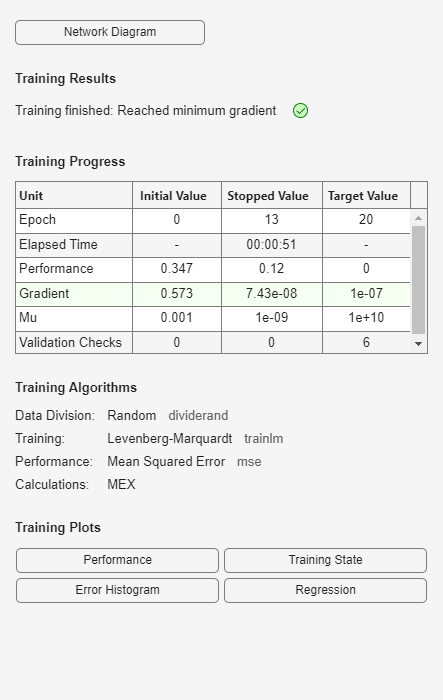

for userID = 1:10
    % Load data for the current user
    filename = sprintf('U%02d_Acc_TimeD_FDay.mat', userID);
    data = load(filename);
    
    % Extract features for the target user
    userFeatures = data.Acc_TD_Feat_Vec;  
    userLabels = ones(size(userFeatures, 1), 1); % Label as 1 for this user

    % Combine other users' data as negative samples
    otherFeatures = [];
    for otherID = 1:10
        if otherID ~= userID
            otherData = load(sprintf('U%02d_Acc_TimeD_FDay.mat', otherID));
            impostorFeatures = otherData.Acc_TD_Feat_Vec;
            
            % Limit to 4 samples per impostor user
            if size(impostorFeatures, 1) > 4
                impostorFeatures = impostorFeatures(1:4, :);
            end
            
            otherFeatures = [otherFeatures; impostorFeatures];
        end
    end
    otherLabels = zeros(size(otherFeatures, 1), 1);
    
    % Combine data for training
    trainFeatures = [userFeatures; otherFeatures];
    trainLabels = [userLabels; otherLabels];

    % Apply PCA on training features
    [coeff, score, latent, tsquared, explained] = pca(trainFeatures);
    reducedFeatures = score(:, 1:70); % Use only the first 70 components
    
    % Determine the number of components to retain 95% variance
    varianceThreshold = 95;
    numComponents = find(cumsum(explained) >= varianceThreshold, 1);
    
    % Reduce dimensionality
    trainFeaturesPCA = score(:, 1:numComponents);

    % Train the FFMLP for the current user
    net = feedforwardnet([50,40,30]);
    
    net.layers{1}.transferFcn = 'tansig';
    net.layers{2}.transferFcn = 'tansig';
    net.layers{3}.transferFcn = 'tansig';
    net.layers{end}.transferFcn = 'logsig';  
    net.performFcn = 'crossentropy';        
    net.trainParam.lr = 0.001;
    net.trainParam.epochs = 20;
   
    % Train the network
    [net, tr] = train(net, trainFeatures', trainLabels');


    % Save the trained network for the user
    userNetworks{userID} = net;
    userPCA{userID} = coeff(:, 1:numComponents); % Save PCA coefficients
end

## Test the trained FFMLP models and calculate metrics

testFeatures = [];
testLabels = [];
predictions = [];
threshold = 0.4;  % Classification threshold

% Load and test all users' data
for userID = 1:10
    % Load test data for the current user
    testFilename = sprintf('U%02d_Acc_TimeD_MDay.mat', userID);
    testData = load(testFilename);
    
    % Append features and labels for each user
    testFeatures = [testFeatures; testData.Acc_TD_Feat_Vec];
    testLabels = [testLabels; ones(size(testData.Acc_TD_Feat_Vec, 1), 1) * userID];
end

% Apply PCA transformation to test data for each user
testFeaturesPCA = cell(1, 10);
for userID = 1:10
    testFeaturesPCA{userID} = testFeatures * userPCA{userID}; % Project test features
end

% Perform classification for all users
for userID = 1:10
    net = userNetworks{userID};
    userPredictions = net(testFeatures')';  % Get predictions for all test features using this user's network
    predictions(:, userID) = userPredictions;  % Store all predictions
end


## Calculate performance metrics and create tables

[~, predictedUserIDs] = max(predictions, [], 2); % Get predicted labels

% Initialize matrices for storing metrics
numUsers = 10;
metrics = zeros(numUsers, 4);  % [ Precision, Recall, F1, Accuracy]
farEerFrr = zeros(numUsers, 3);  % [FAR, FRR, EER]

% Calculate metrics for each user
for userID = 1:numUsers
    actualLabels = testLabels == userID;
    predictedLabels = predictedUserIDs == userID;
    
    % Basic metrics
    TP = sum(predictedLabels == 1 & actualLabels == 1);
    TN = sum(predictedLabels == 0 & actualLabels == 0);
    FP = sum(predictedLabels == 1 & actualLabels == 0);
    FN = sum(predictedLabels == 0 & actualLabels == 1);
    
    % Calculate precision, recall, F1
    precision = TP / (TP + FP);
    recall = TP / (TP + FN);
    f1 = 2 * (precision * recall) / (precision + recall);
    accuracy = (TP + TN) / (TP + TN + FP + FN);
    
    % Store in metrics matrix
    metrics(userID, :) = [precision, recall, f1, accuracy];
    
    % Calculate FAR and FRR for various thresholds
    genuineScores = predictions(actualLabels, userID);
    impostorScores = predictions(~actualLabels, userID);
    
    for tIdx = 1:length(thresholds)
        threshold = thresholds(tIdx);
        FARs(userID, tIdx) = mean(impostorScores >= threshold);
        FRRs(userID, tIdx) = mean(genuineScores < threshold);
    end
    
    % Find EER
    [~, minIdx] = min(abs(FARs(userID, :) - FRRs(userID, :)));
    farEerFrr(userID, :) = [FARs(userID, minIdx), FRRs(userID, minIdx), ...
        (FARs(userID, minIdx) + FRRs(userID, minIdx)) / 2];
end

% Create performance metrics table
performanceTable = array2table(metrics, ...
    'VariableNames', {'Precision', 'Recall', 'F1_Score', 'Accuracy'}, ...
    'RowNames', arrayfun(@(x) sprintf('User %d', x), 1:numUsers, 'UniformOutput', false));

% Create FAR, FRR, EER table
farEerFrrTable = array2table(farEerFrr * 100, ...  % Convert to percentage
    'VariableNames', {'FAR', 'FRR', 'EER'}, ...
    'RowNames', arrayfun(@(x) sprintf('User %d', x), 1:numUsers, 'UniformOutput', false));


overallRates = array2table([...
    mean(metrics); % Average Precision, Recall, F1, Accuracy
    ], ...
    'VariableNames', {'Precision', 'Recall', 'F1_Score', 'Accuracy'}, ...
    'RowNames', {'Average'});

overallErrorRates = array2table([...
    mean(farEerFrr) * 100  % Average FAR, FRR, EER in percentage
    ], ...
    'VariableNames', {'FAR', 'FRR', 'EER'}, ...
    'RowNames', {'Average'});


##  Display performance metrics and error rates

disp('Performance Metrics Table:');

Performance Metrics Table:


disp(performanceTable);

               Precision     Recall     F1_Score    Accuracy
               _________    ________    ________    ________

    User 1            1            1          1           1 
    User 2            1            1          1           1 
    User 3            1            1          1           1 
    User 4            1      0.94444    0.97143     0.99444 
    User 5      0.94595      0.97222     0.9589     0.99167 
    User 6            1            1          1           1 
    User 7      0.66038      0.97222    0.78652     0.94722 
    User 8          0.9         0.25     0.3913     0.92222 
    User 9      0.25316      0.55556    0.34783     0.79167 
    User 10           

disp(' ');

disp('Error Rates Table (%):');

Error Rates Table (%):


disp(farEerFrrTable);

                 FAR       FRR        EER  
               _______    ______    _______

    User 1     0.92593         0    0.46296
    User 2           0         0          0
    User 3     0.92593         0    0.46296
    User 4      4.0123    2.7778     3.3951
    User 5      1.5432    2.7778     2.1605
    User 6     0.61728         0    0.30864
    User 7      7.4074    2.7778     5.0926
    User 8           0         0          0
    User 9      21.296    13.889     17.593
    User 10          0         0          0



disp(' ');

disp('Overall Performance Rates:');

Overall Performance Rates:


disp(overallRates);

               Precision    Recall     F1_Score    Accuracy
               _________    _______    ________    ________

    Average     0.87595     0.77778    0.76098     0.95556 



disp(' ');

disp('Overall Error Rates (%):');

Overall Error Rates (%):


disp(overallErrorRates);

                FAR       FRR       EER  
               ______    ______    ______

    Average    3.6728    2.2222    2.9475




% Format numbers in tables for better readability
format = '%.2f';
performanceTable = varfun(@(x) num2str(x, format), performanceTable);
farEerFrrTable = varfun(@(x) num2str(x, format), farEerFrrTable);



## Plot FAR vs FRR curves

figure;
hold on;
for userID = 1:numUsers
    plot(thresholds, FARs(userID, :), 'b-', 'DisplayName', sprintf('FAR User %d', userID));
    plot(thresholds, FRRs(userID, :), 'r-', 'DisplayName', sprintf('FRR User %d', userID));
end
xlabel('Threshold');
ylabel('Rate');
title('FAR vs FRR Curves for All Users');
legend('show');
grid on;
hold off;